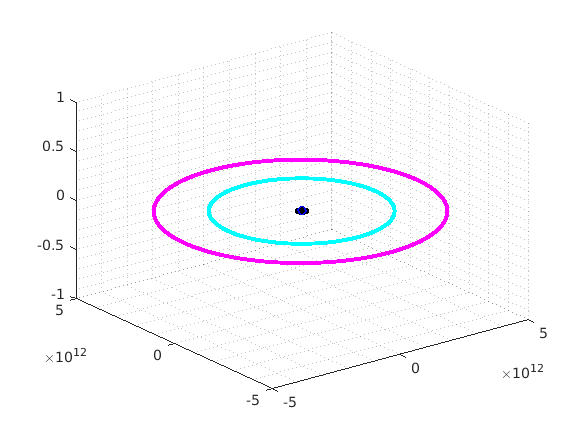

global G m;
G = 6.67428E-11; % m3 kg-1 s-2
 mS = 1.989E30; % kg - masa de la Sol
 rS = 6.96340E8; % radio del Sol m



mT = 5.976E24; % kg - masa del Tierra
rT = 6.371E6; % radio de la Tierra m
hT = 1.496E11; % altura Tierra m

m = [mS; mT];

ds = rT + rS + hT; % distancia entre centros de masa
r0 = [ [0;0;0]; [ds;0;0] ]; % [rS; rT]
Ts = 365*24*60*60; % periodo en s
ws = 2*pi/Ts; % velocidad angular
vs = ws*ds; % velocidad tangencial sqrt(G * mS/ds)
v0 = [ [0;0;0]; [0;vs;0] ]; % [vT; vs]

nv = 4; % número de vueltas
tf = nv*Ts;
h = 60; % 60 s = 1 minuto 

y0 = [r0;v0];
fhandle = @f; % creation of the function handle of a named function
[t,y] = RK4(fhandle,y0,0,tf,h); 


plot3(y(1,:),y(2,:),y(3,:),'ob');
hold on;
plot3(y(4,:),y(5,:),y(6,:),'.k');
grid minor;





 mU = 8.683E25; % kg - masa del Urano
m = [mS; mU];

rU = 2.5362E7; % radio de Urano m
hU = 2.871E12; % altura Urano m
ds = rU + rS + hU; % distancia entre centros de masa
r0 = [ [0;0;0]; [ds;0;0] ]; % [rS; rU]
Ts = 84*365*24*60*60; % periodo en s
ws = 2*pi/Ts; % velocidad angular
vs = ws*ds; % velocidad tangencial sqrt(G * mS/ds)
v0 = [ [0;0;0]; [0;vs;0] ]; % [vT; vs]

nv = 4; % número de vueltas
tf = nv*Ts;
h = 24*60*60; % 60 s = 1 minuto 

y0 = [r0;v0];
fhandle = @f; % creation of the function handle of a named function
[t2,y2] = RK4(fhandle,y0,0,tf,h); 

plot3(y2(1,:),y2(2,:),y2(3,:),'ob');
hold on;
plot3(y2(4,:),y2(5,:),y2(6,:),'.c');
grid minor;



mN = 1.024E26; % kg - masa del Neptuno
m = [mS; mN];

rN = 2.4622E7; % radio de Neptuno m
hN = 4.498E12; % altura Neptuno m
ds = rN + rS + hN; % distancia entre centros de masa
r0 = [ [0;0;0]; [ds;0;0] ]; % [rS; rU]
Ts = 164*365*24*60*60; % periodo en s
ws = 2*pi/Ts; % velocidad angular
vs = ws*ds; % velocidad tangencial sqrt(G * mS/ds)
v0 = [ [0;0;0]; [0;vs;0] ]; % [vT; vs]

nv = 4; % número de vueltas
tf = nv*Ts;
h = 24*60*60; % 60 s = 1 minuto 

y0 = [r0;v0];
fhandle = @f; % creation of the function handle of a named function
[t3,y3] = RK4(fhandle,y0,0,tf,h); 


plot3(y3(1,:),y3(2,:),y3(3,:),'ob');
hold on;
plot3(y3(4,:),y3(5,:),y3(6,:),'.m');
grid minor;

function ydot = f(~,y)
 global G m;
 r = y(1:6); % vectores de posición rT y rS
 v = y(7:12);
 dr = r(4:6) - r(1:3); % dr va de la Tierra al satélite s-T
 u = dr / norm(dr);
 dr2 = norm(dr)^2;
 F = (G*m(1)*m(2)/dr2) * u;
 a = [F/m(1); -F/m(2)]; % par acción - reacción; tercera ley de Newton
 ydot = [v;a];
end




function [t,y] = RK4(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    m = length(y0);
    y = zeros(m,n);
    y(:,1) = y0;
    for i = 1:n-1
        k1 = f(t(i),y(:,i));
        k2 = f(t(i)+(1/2)*h,y(:,i)+(1/2)*k1*h);
        k3 = f(t(i)+(1/2)*h,y(:,i)+(1/2)*k2*h);
        k4 = f(t(i)+h,y(:,i)+k3*h);
        y(:,i+1) = y(:,i) + (k1+2*k2+2*k3+k4)/6 *h;
    end
end



